# Progsheet 1 - Introduction to the Numerics of partial differential equations

*Author: Sven Ullmann and Jonathan Schnitzler*

This is an exercise sheet in one space and one time dimension.

## Cars on a road

We consider the initial-boundary value-problem for a unknown $u\in C^1 \left(\Omega {\;}_{T\;} \right)$

        $\partial {\;}_t u\left(x,t\right)+\partial {\;}_x F\left\lbrack u\left(x,t\right)\right\rbrack =0$         in $\Omega {\;}_T$

                                    $u\left(\cdot ,0\right)=u_0$      in $\Omega \;$

        $\partial {\;}_x u\left(x_{\min } ,\cdot \;\right)=\partial {\;}_x u\left(x_{\max } ,\cdot \;\right)$           in $\left(0,T\right)$

We define 

%Domain
x_min = 0;
x_max = 5;
T = 1;


%Discretication
nt = 100;
dt = T/nt,

dt = 0.0100


nx = 250;
dx = (x_max - x_min)/nx,

dx = 0.0200

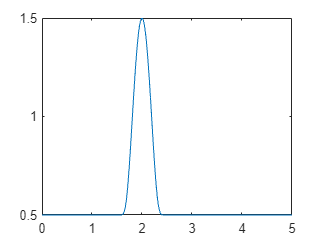



omega = linspace(x_min, x_max, nx);
omega_time = linspace(0,T,nt);


%Boundary values
u0 = initial_values(omega);
plot(omega, u0)


%Non Linear Function F
f = @(u) u.*(1-u)

f = function_handle with value:
    @(u)u.*(1-u)


### Flux kernels G

We will consider different flux kernels with which we will solve the iterative scheme for this PDE

#### General iterative scheme


$$u_j^{\left(n+1\right)} :=u_j^n -\frac{\Delta t\;}{\Delta x}\left(G_{\left(j+\frac{1}{2}\right)}^n -G_{\left(j-\frac{1}{2}\right)}^n \right)$$


$u_J^n :=u_0^n$ (cars are in a closed loop)

%Initialization
u = zeros(nt,nx);
u(1,:) = u0;

%Placeholder for flux kernel
G = @(u,n,j,dt,dx) 0           %+1/2 -> 1 and -1/2 ->0

G = function_handle with value:
    @(u,n,j,dt,dx)0


% SPECIAL CASE: j = 0 and flux 0-1/2
Gs = @(u,n,dt,dx) 0

Gs = function_handle with value:
    @(u,n,dt,dx)0



for n = 1:(nt-1)
        u(n+1, 1) = u(n,1) - dt/dx .* (G(u,n,2,dt,dx) - Gs(u,n,dt,dx));
        u(n+1, end) = u(n+1,1);
        for j = 2:(nx-1)
            u(n+1, j) = u(n,j) - dt/dx .* (G(u,n,j+1,dt,dx)- G(u,n,j,dt,dx));
        end
end

%Which can be vectorized by assembling to a matrix

In the following we collect the implementation of the different fluxes, which are also saved as a `flux.m` file where the specification is entered as the last argument with a string 

`spec = lax `or 

`spec = up `or lastly 

`spec = down`.

#### Lax-Friedrichs


$$G_{j+\frac{1}{2}}^n =\frac{u_j^n \left(1-u_j^n \right)+u_{j+1}^n \left(1-u_{j+1}^n \right)}{2}-\frac{\Delta x\;}{2\Delta t}\left(u_{j+1}^n -u_j^n \right)$$



$$G_{-\frac{1}{2}}^n =\frac{u_J^n \left(1-u_J^n \right)+u_1^n \left(1-u_1^n \right)}{2}-\frac{\Delta x\;}{2\Delta t}\left(u_1^n -u_J^n \right)$$


G = @(u,n,j,dt,dx) (u(n,j-1).*(1-u(n,j-1)) + u(n,j).*(1-u(n,j)))/2 - dx/(2.*dt).*(u(n,j)-u(n,j-1));
Gs = @(u,n,dt,dx) (u(n,end).*(1-u(n,end)) + u(n,1).*(1-u(n,1)))/2 - dx/(2.*dt).*(u(n,1)-u(n,end));
% Assuming there is a typo in the worksheet, and it should use the first
% value (i.e. u_0)

*Anmerkung: In python könnte man Gs sehr elegant implementieren, da bei negativer indiziierung der von dem letzten Wert gezählt wird, was genau die richtige Funktion implementieren würde.*

#### "Upwind"-Flux


$$G_{j+\frac{1}{2}}^n =u_j^n \left(1-u_j^n \right)$$



$$G_{-\frac{1}{2}}^n =u_J^n \left(1-u_J^n \right)$$


G = @(u,n,j,dt,dx) u(n,j-1).*(1-u(n,j-1));
Gs = @(u,n,dt,dx) u(n,end).*(1-u(n,end));

#### "Downwind"-Flux


$$G_{j+\frac{1}{2}}^n =u_{j+1}^n \left(1-u_{j+1}^n \right)$$



$$G_{-\frac{1}{2}}^n =u_0^n \left(1-u_0^n \right)$$


G = @(u,n,j,dt,dx) u(n,j).*(1-u(n,j));
Gs = @(u,n,dt,dx) u(n,1).*(1-u(n,1)); 

I used different notation since I found +1/2 is a bit awkward i just fancied clearity over symmetrie and choose $j+\frac{1}{2}\to j+1$ and $j-\frac{1}{2}\to j$

### Evaluation

type = ["lax","up","down"]

type = 1×3 string array
    "lax"    "up"    "down"


ty = "lax"

G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


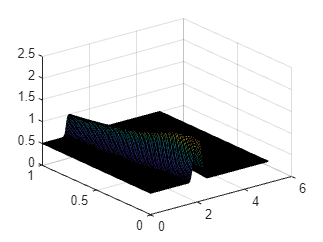

ty = "up"

G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j-1).*(1-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,end).*(1-u(n,end))


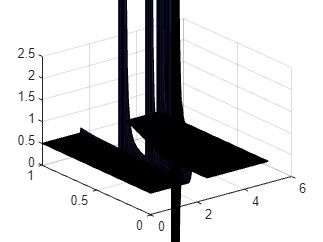

ty = "down"

G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


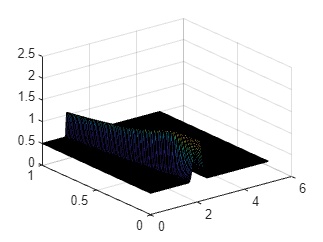

for ty = type
    ty
    u = zeros(nt,nx);
    u(1,:) = u0;
    
    [G,Gs] = flux(ty)
    
    for n = 1:(nt-1)
        u(n+1, 1) = u(n,1) - dt/dx .* (G(u,n,2,dt,dx) - Gs(u,n,dt,dx));
        u(n+1, end) = u(n+1,1);
        for j = 2:(nx-1)
            u(n+1, j) = u(n,j) - dt/dx .* (G(u,n,j+1,dt,dx)- G(u,n,j,dt,dx));
        end
    end
    [X, Y] = meshgrid(omega,omega_time);
    figure
    surf(X,Y,u)
    zlim([0 2.5])
end

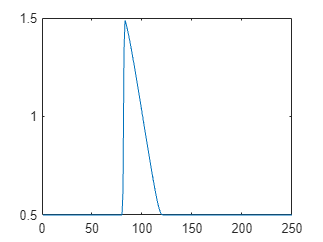


for tt = 1:20
    plot(u(tt,:))
    zlim([0 2.5])
%     hold on
end

#### Testing and cutting

timeInstances = 0:0.25:T, %Generate multiple evaluation for time instances

timeInstances =          0    0.2500    0.5000    0.7500    1.0000


type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


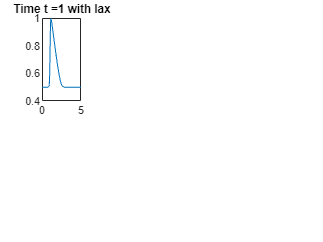

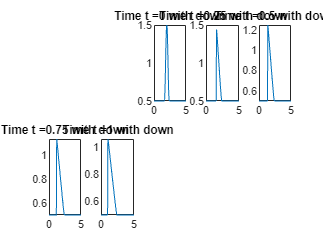

type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


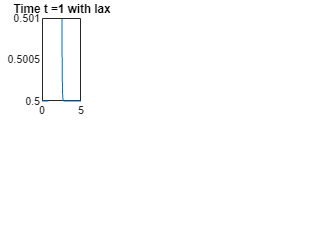

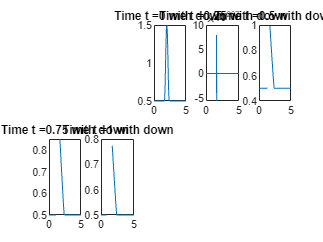

type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


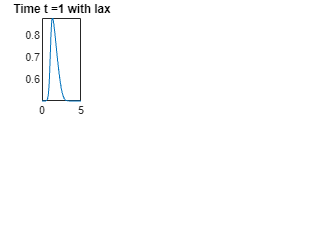

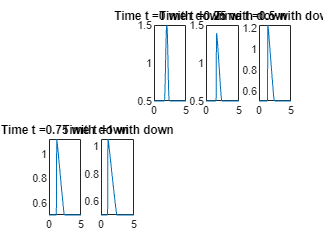

type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


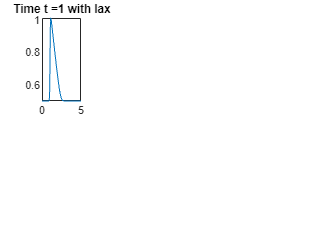

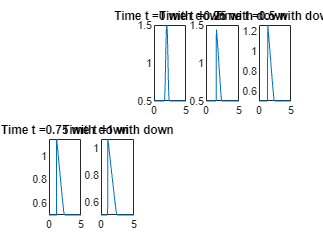

type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


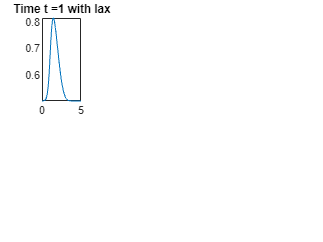

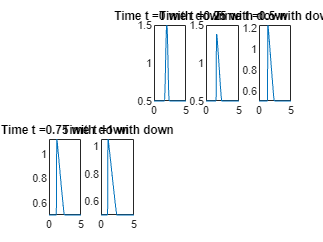

type = 1×2 string array
    "lax"    "down"


G = function_handle with value:
    @(u,n,j,dt,dx)(u(n,j-1).*(1-u(n,j-1))+u(n,j).*(1-u(n,j)))/2-dx/(2.*dt).*(u(n,j)-u(n,j-1))


Gs = function_handle with value:
    @(u,n,dt,dx)(u(n,end).*(1-u(n,end))+u(n,1).*(1-u(n,1)))/2-dx/(2.*dt).*(u(n,1)-u(n,end))


G = function_handle with value:
    @(u,n,j,dt,dx)u(n,j).*(1-u(n,j))


Gs = function_handle with value:
    @(u,n,dt,dx)u(n,1).*(1-u(n,1))


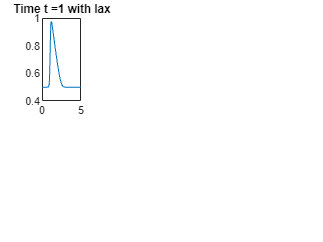

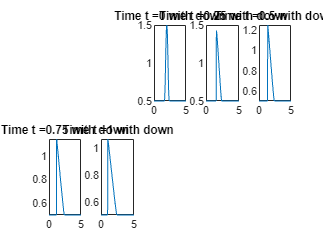


ntArr = 100:200:500;
dtArr = T./ntArr;

nxArr = [250,500];
dxArr = (x_max - x_min)./nxArr;


for nt = ntArr
    dt = T/nt;
    for nx = nxArr
        dx = (x_max-x_min)./nx;
        
        omega = linspace(x_min, x_max, nx);
        omega_time = linspace(0,T,nt);
        u0 = initial_values(omega);
        
        uAll = zeros(nt,nx,3);
        type = ["lax","up","down"]
        
        %Calculation for all three types
        for ty = 1:numel(type)
            u = zeros(nt,nx);
            u(1,:) = u0;
            [G,Gs] = flux(type(ty));
            
            
            for n = 1:(nt-1)
                u(n+1, 1) = u(n,1) - dt/dx .* (G(u,n,2,dt,dx) - Gs(u,n,dt,dx));
                u(n+1, end) = u(n+1,1);
                for j = 2:(nx-1)
                    u(n+1, j) = u(n,j) - dt/dx .* (G(u,n,j+1,dt,dx)- G(u,n,j,dt,dx));
                end
            end
            
            
            uAll(:,:,ty) = u;
%             [X, Y] = meshgrid(omega,omega_time);
%             figure
%             surf(X,Y,u)
%             zlim([0 2.5])
            
            
        end
        
        
        %Plotting
        figure
        for ty = 1:numel(type)
            for ti = 1:numel(timeInstances)
                subplot(numel(type),numel(timeInstances),ty+((ty-1)*ti))
%                 floor(ti./T.*(nt-1))+1
                plot(omega,uAll(floor(timeInstances(ti)./T.*(nt-1))+1,:,ty))
                title("Time t =" + string(timeInstances(ti)) + " with " + type(ty))
            end
            
        end

        %Or in multiple plots
        figure
        for ti = 1:numel(timeInstances)
            for ty = 1:numel(type)
                subplot(numel(type),1,ty)
%                 floor(ti./T.*(nt-1))+1
                plot(omega,uAll(floor(timeInstances(ti)./T.*(nt-1))+1,:,ty))
                title("Time t =" + string(timeInstances(ti)) + " with " + type(ty))
            end
        end
        
        
    end
end

### More efficient implementation

Matrix, ...